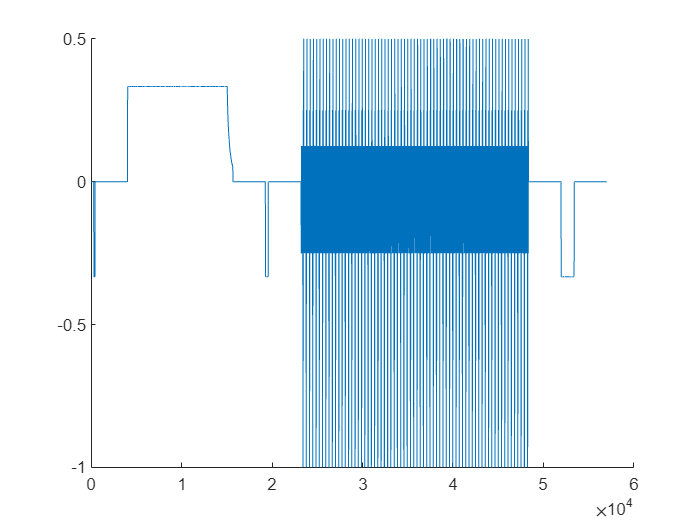

% clc;
% clear;

k=-2:0.01:2;

Dsn=2.5e-13;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

epssn=0.471;
epssp=0.297;

A=1;

F=96485.33289;

Jn=-17.5*Rsn/3/epssn/F/A/Ln;
Jp=17.5*Rsp/3/epssp/F/A/Lp;

Jn_vector=ones(1,1500)*Jn.*k';
Jp_vector=ones(1,1500)*Jp.*k';

load train_data\dcsen_cc.mat;
load train_data\dcsep_cc.mat;

load dynamics_load\FUDS_C.mat;
load dynamics_load\DST_C.mat;
load dynamics_load\NEDC_C.mat;

I_FUDS=17.5*[FUDS_C(33523:34992);zeros(500,1)];
I_NEDC=17.5*[NEDC_C(23105:24392);zeros(500,1)];
I_DST=17.5*[DST_C(23085:23548);zeros(100,1)];

Jn_FUDS=I_FUDS*Rsn/3/epssn/F/A/Ln;
Jp_FUDS=-I_FUDS*Rsp/3/epssp/F/A/Lp;

Jn_DST=I_DST*Rsn/3/epssn/F/A/Ln;
Jp_DST=-I_DST*Rsp/3/epssp/F/A/Lp;

Jn_NEDC=I_NEDC*Rsn/3/epssn/F/A/Ln;
Jp_NEDC=-I_NEDC*Rsp/3/epssp/F/A/Lp;

for i=1:401
    dcsep_fuds(i,:)=simCsePDE(Rsp,Dsp,Jp_FUDS*k(i));
    dcsen_fuds(i,:)=simCsePDE(Rsn,Dsn,Jn_FUDS*k(i));
end

for i=1:401
    dcsep_nedc(i,:)=simCsePDE(Rsp,Dsp,Jp_NEDC*k(i));
    dcsen_nedc(i,:)=simCsePDE(Rsn,Dsn,Jn_NEDC*k(i));
end

for i=1:401
    dcsep_dst(i,:)=simCsePDE(Rsp,Dsp,Jp_DST*k(i));
    dcsen_dst(i,:)=simCsePDE(Rsn,Dsn,Jn_DST*k(i));
end

% figure(1);
% clf;
% hold on;
% plot(DST_C);

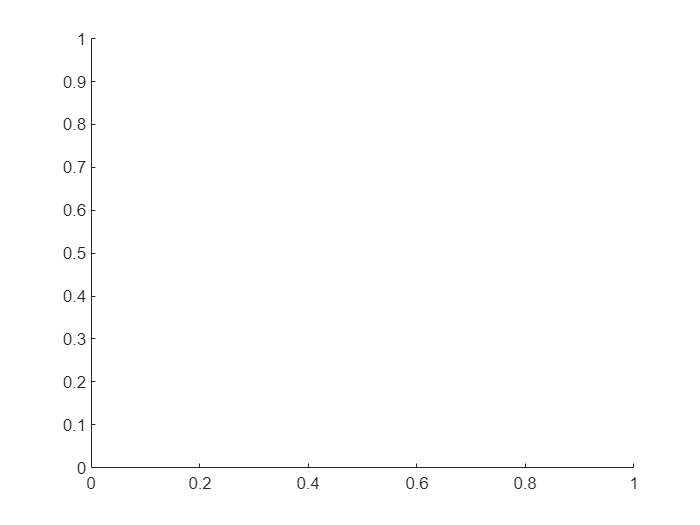


% figure(2);
% clf;
% hold on;

% pcolor(dcsen_fuds);

函数或变量 'dcsen_fudc' 无法识别。

% shading interp;
% colorbar;
% colormap("spring");